## Projekt nr 1

W ramach projektu nr 1 przygotujemy program obliczający parametry ruchu skoczka bungee, skaczącego z podnośnika koszowego, znajdującego się na wysokości $h$ nad poziomem terenu. W zadaniu, początek układ współrzędnych $x-y$ umieszczony został w miejscu zamocowania liny do kosza podnośnika (zobacz rysunek poniżej). Skoczek uproszczony został do punktowej masy $m$ i znajduje się w odległości $x_s$ oraz $y_s$ od punktu zamocowania liny. Podczas lotu skoczka zakładamy, że na skoczka działa siła grawitacji $\vec{G}$,  siła sprężystości liny $\vec{S}$, wywołana jej wydłużeniem, a także siły oporów ruchu $\vec{O}$ działające na skoczka oraz linę. Pominiemy natomiast wpływ wiatru oraz założymy sztywny podnośnik.

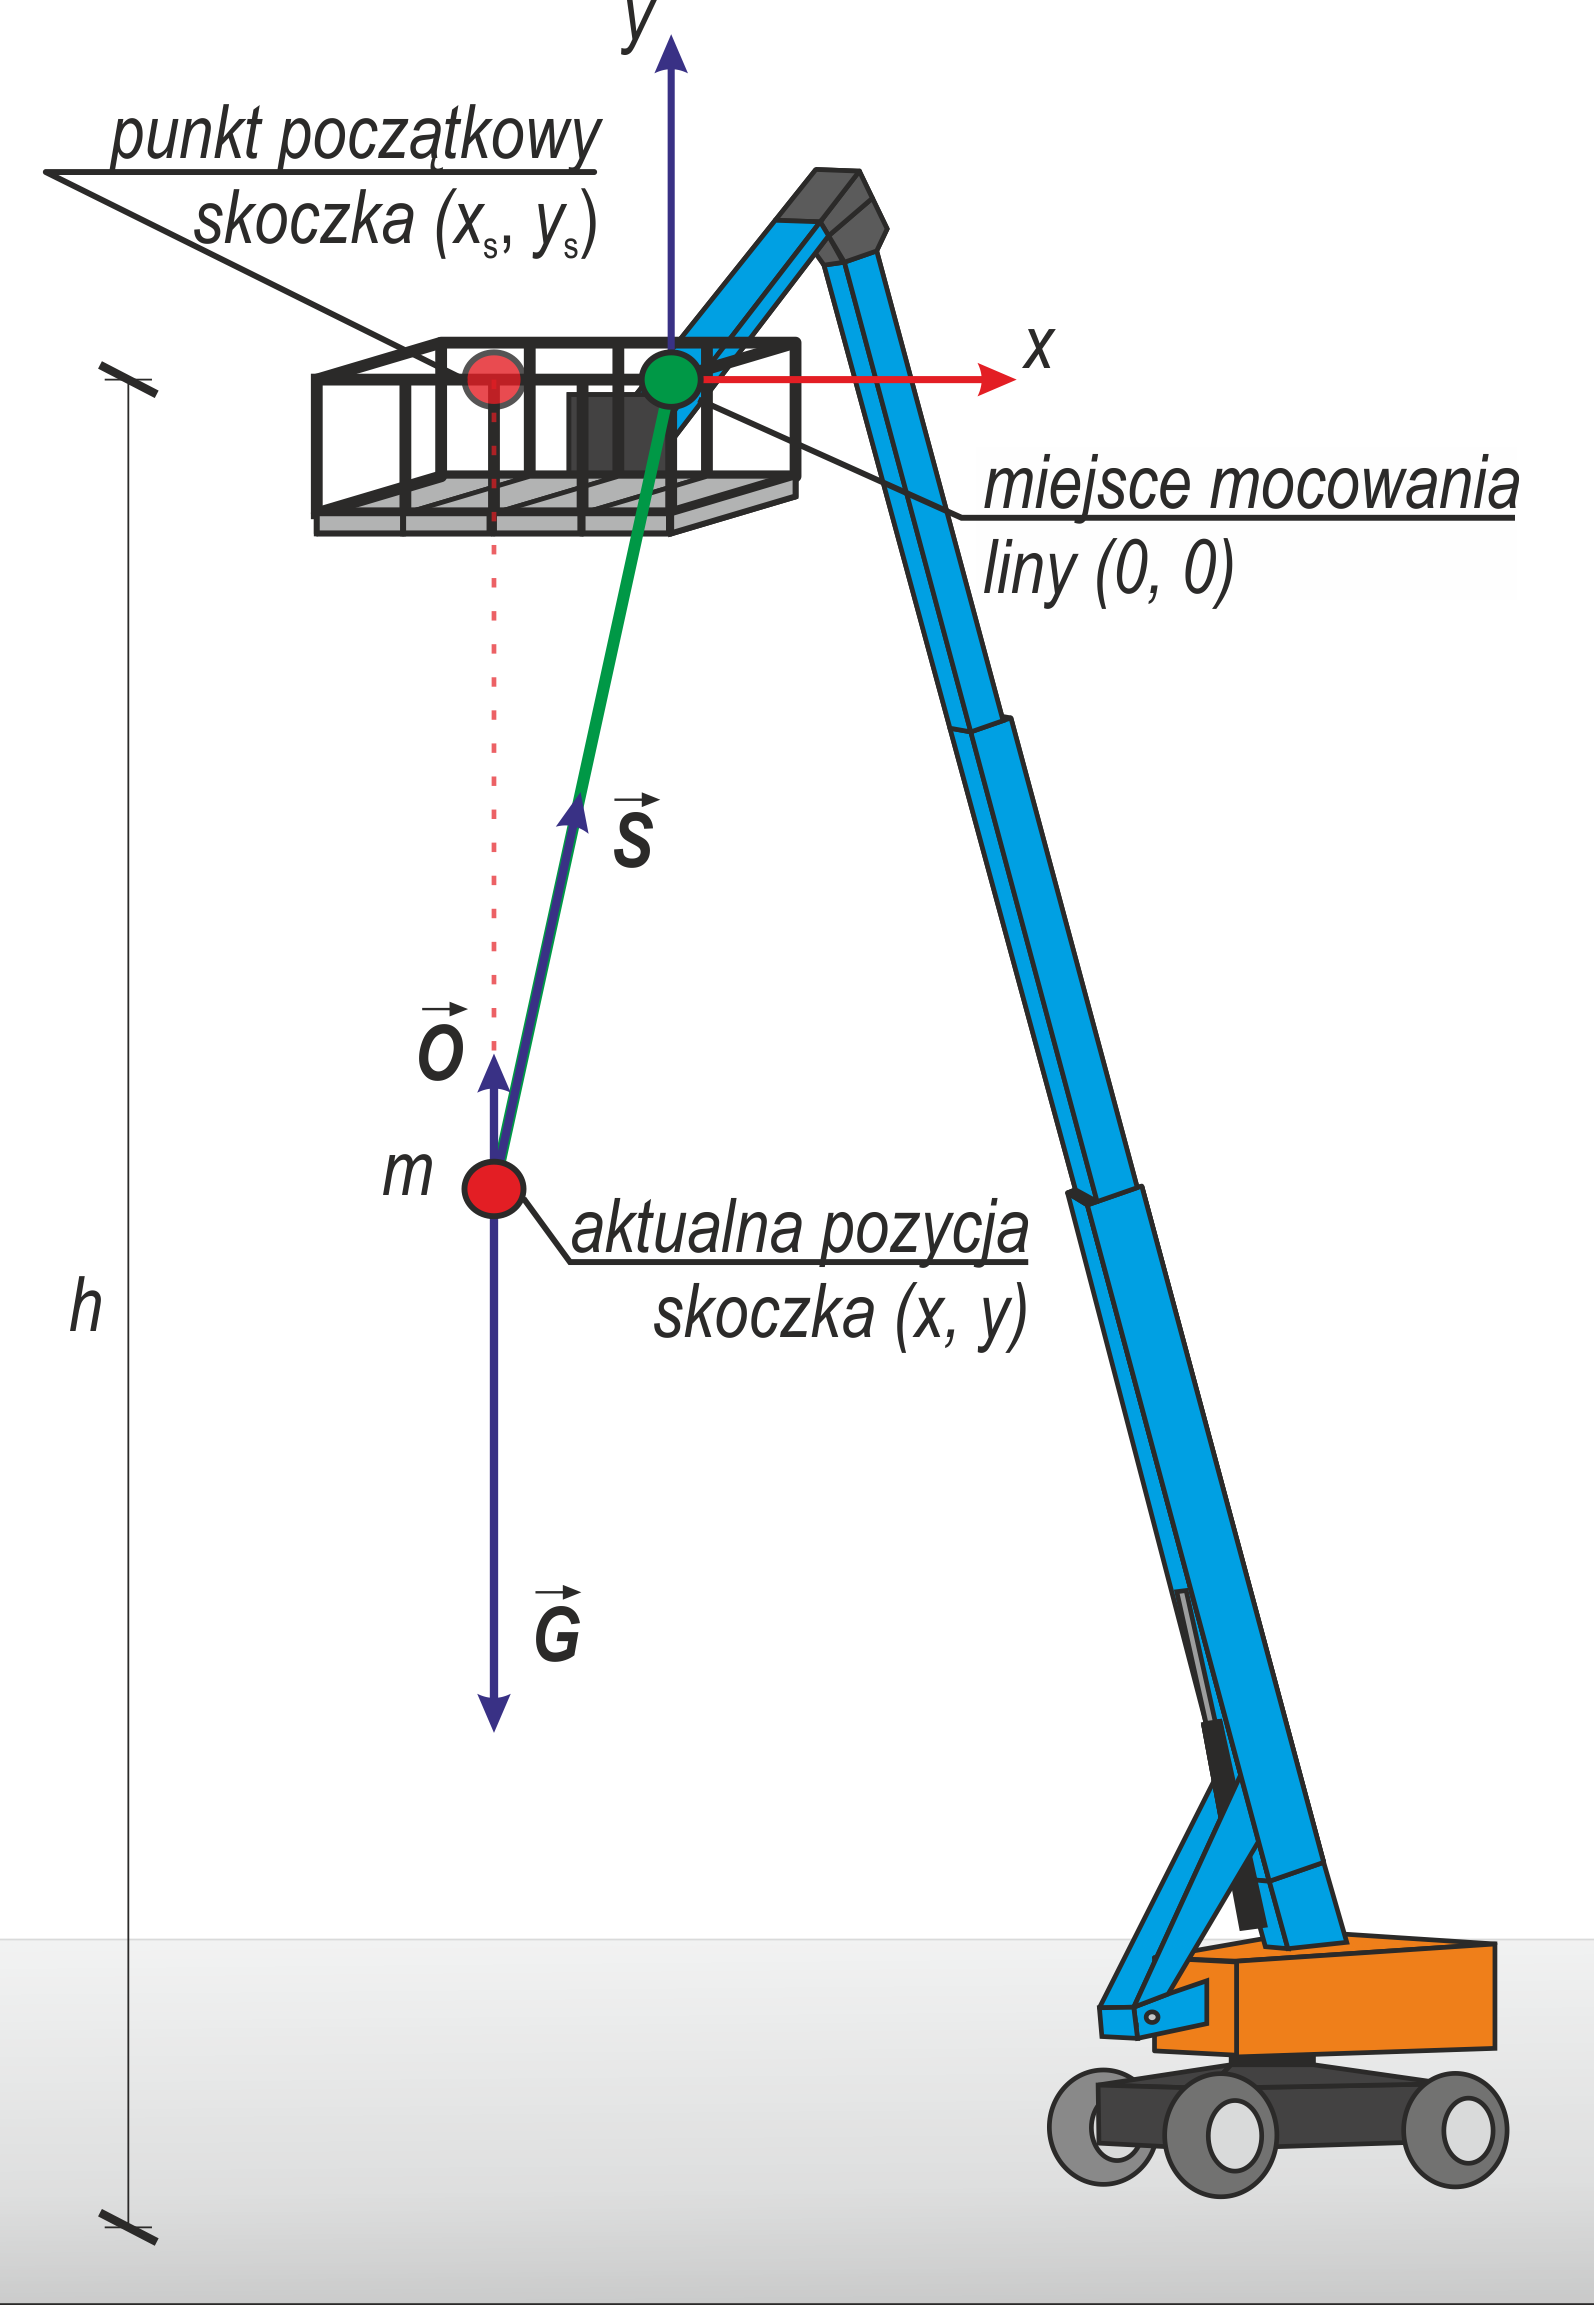

Na samym początku upewnimy się, że w pamięci nie są przechowywane żadne zbędne zmienne.

clear; clc; close all;

Następnie przyjmijmy, że wysokość kosza nad terenem to $h = 30 \textrm{ m}$, masa skoczka to $m = 80 \textrm{ kg}$, a do tego, że skoczek znajduje się jeden metr na lewo oraz na tej samej wysokości co punkt mocowania liny, tj. $x_s = -1 \textrm{ m}$ oraz $y_s = 0 \textrm{ m}$. 

h  = 30;                % wysokość dźwigu (m)
m  = 80;                % masa skoczka (kg)
xs = -1;  ys = 0;       % pozycja początkowa skoczka (xs,ys) (m)

Aby obliczyć siłę grawitacji $\vec{G}$ przyjmijmy przyspieszenie grawitacyjne $g=9.81 \textrm{ m/s}^2$. Siła $\vec G$ jest iloczynem masy skoczka oraz przyspieszenia grawitacyjnego.

g = 9.81;                % przyspieszenie grawitacyjne (m/s2)

Siłę sprężystości liny, $\vec S$ możemy w przybliżeniu wyrazić jako iloczyn sztywności liny oraz jej wydłużenia. Schemat działania liny bungee można uprościć do działania sprężyny, której sztywność maleje wraz z wydłużeniem. W związku z tym można zastosować uproszczony model, gdzie sztywność liny będzie wynosiła $k_1$, dla wydłużenia mniejszego od $e_b$, a następnie $k_2$, dla wydłużenia większego od $e_b$, gdzie $k_1>k_2$. 

Przyjmijmy linę bungee o długości początkowej $L = 10 \textrm{ m}$ i parametrach $k_1=200 \textrm{ N/m}$, $k_2=110 \textrm{ N/m}$ oraz $e_b = 5 \textrm{ m}$.

k_1 = 200;              % sztywność dla e < e_b (N/m)
k_2 = 110;              % sztywność dla e > e_b (N/m)
e_b = 5;                % wydłużenie przy którym zmienia się sztywność (m)
k = [k_1 k_2];          % model sztywności liny bungee
L  = 10;                % długość początkowa liny bungee (m) 

W naszym uproszczonym modelu przyjmijmy również, że siła oporów ruchu, $\vec O$, jest wprost proporcjonalna do kwadratu prędkości skoczka. Aby wyznaczyć współczynnik proporcjonalności, $d$, potrzebne nam będzie określenie dodatkowych parametrów skoczka oraz otaczającego go powietrza. Przyjmijmy gęstość powietrza $\rho=1.2 \textrm{ kg/m}^3$, współczynnik oporu aerodynamicznego $c_x = 1$ (dla spadochroniarza spadającego na płasko) oraz powierzchnię rzutu ciała średniego człowieka $a_c = 0.8 \textrm{ m}^2$. Współczynnik oporów ruchu $d$, obliczymy wtedy jako iloczyn zdefiniowanych parametrów, wyrażony w jednostce $ \frac{\textrm{N}\cdot \textrm{s}^2}{\textrm{m}^2}$.

rho = 1.2;              % gęstość powietrza (kg/m3)
cx = 1.0;               % współczynnik oporu aerodynamicznego 
ac = 0.8;               % powierzchnia rzutu ciała człowieka (m2)
d = rho*cx*ac;          % współczynnik oporów ruchu (N*s2/m2)

Na koniec definicji danych ustalmy sobie czas trwania symulacji skoku $t_{max}=30 \textrm{ s}$ oraz liczbę kroków czasowych, dla których obliczane będą parametry ruchu $nt = 100000$.

**Uwaga**. Rozwiązanie tego zadania jest rozwiązaniem przybliżonym i zależy bezpośrednio od liczby kroków czasowych. W związku z tym parametr $nt$ powinien być odpowiednio duży, aby rozwiązanie było poprawne.

t_max = 30;              % maksymalny czas (s)
nt = 100000;             % liczba kroków czasowych 

## 1. Inicjalizacja tablic

W pierwszym kroku rozwiązania, po definicji danych, tworzymy tablice, które będą potrzebne do obliczania parametrów ruchu. Innymi słowy, w tym kroku rezerwujemy sobie miejsce w pamięci komputera, aby był on zdolny przechowywać wszystkie wymagane liczby. W związku z tym, zainicjalizować należy tablice związane z czasem, pozycją skoczka oraz długością liny, prędkością oraz przyspieszeniem skocza, a także tablice zawierające siły na niego działające. 

**Odpowiednie funkcje piszemy samodzielnie, zgodnie z instrukcją zawartą w komentarzu wewnątrz funkcji.**

%%% Funkcje poniżej uzupełniamy samodzielnie
[t,dt]    = inicjalizacja_czasu(t_max,nt);
[x,y,r,e] = inicjalizacja_pozycji(nt);
[V]       = inicjalizacja_predkosci(nt);
[A]       = inicjalizacja_przyspieszen(nt);
[G,S,O,F] = inicjalizacja_sil(m,g,nt);

## 2. Krok początkowy obliczeń

W kolejnym kroku należy określić początkową pozycję skoczka, tzn. ustalamy, że współrzędne $x, y$ w pierwszym kroku będą wynosiły odpowiednio $x_s$ oraz $y_s$. Następnie, na tej podstawie wyznaczamy początkową długość liny bungee $r_1=\sqrt{x_s^2+y_s^2}$. Kolejnym etapem jest określenie początkowych sił działających na skoczka i wprowadzenie ich do macierzy sił $\textbf{F}$. Przypomnijmy, że przyjęto konwencję, że numer wiersza macierzy odpowiada kolejnej chwili czasowej, a kolumny $1$, $2$ i $3$ odpowiadają odpowiednio składowej na kierunku $x$, $y$ oraz wypadkowej wektora. 

W pierwszym kroku siła składowa na kierunku $x$ wynosić będzie 0, co oznaczane będzie jako $\textbf{F}_{1,x} \equiv \textbf{F}(1,1) = 0$. Analogicznie wprowadzamy siłę wypadkową na kierunku y dla pierwszego kroku, tj. $\textbf{F}_{1,y} \equiv \textbf{F}(1,2) = \textbf{G}(1,2)$, gdzie $\textbf{G}$ zdefiniowano podczas inicjalizacji tablic sił powyżej. Następnie, na podstawie składowych siły wyznaczamy ich wypadkową, tj. $\textbf{F}_{1,w} \equiv \textbf{F}(1,3)=\sqrt{\textbf{F}_{1,x}^2 + \textbf{F}_{1,y}^2}$. Mając wyznaczoną siłę wypadkową, która działa na skoczka, możemy obliczyć przyspieszenie jakiego on doznaje, zgodnie z $\textbf{A}_1 = \textbf{F}_1 \ / \ m$.

x(1) = xs; 
y(1) = ys;
r(1) = sqrt(x(1)^2 + y(1)^2);

F(1,1) = 0;
F(1,2) = G(1,2);
F(1,3) = sqrt(F(1,1)^2 + F(1,2)^2);

A(1,:) = F(1,:)./m;

## 3. Całkowanie równań ruchu

Korzystając z określonych powyżej, początkowych parametrów ruchu, możemy przejść do obliczania tych parametrów dla kolejnych kroków czasowych. W związku z tym konieczne jest napisanie pętli, która będzie przebiegała po krokach od $2$ do $nt$ (dla kroku 1 parametry wyznaczyliśmy w poprzednim podpunkcie). 

Następnie, dla kolejnych kroków obliczeniowych wyznaczamy wielkości, takie jak prędkość skoczka, pozycję skoczka oraz parametry liny. W tym celu wykorzystamy funkcje, które należy uzupełnić samodzielnie. Na tym etapie zdefiniujmy sobie, że krok $i$ oznacza krok *aktualny*, a krok $i-1$ oznaczał będzie krok *poprzedni*. Wartość przyrostu czasu $dt$ wyznaczana była na etapie inicjalizacji zmiennych i dla przyjętych powyżej założeń $dt = 0.0003 \textrm{ s}$. To na tyle czasu w przód będziemy "przewidywać" parametry ruchu skoczka.

### 3.1 Prędkość skoczka

Zaczniemy od funkcji obliczającej *aktualną* prędkość skoczka, bazując na wielkościach z kroku *poprzedniego*. W tym celu skorzystamy z następujących wzorów: 

- $v_{i,x}=v_{i-1,x}+a_{i-1,x} \cdot dt$, 

- $v_{i,y}=v_{i-1,y}+a_{i-1,y} \cdot dt$,

- $v_{i,w}=\sqrt{v_{i,x}^2+v_{i,y}^2}$ ,

- $\textbf{V}_i = [v_{i,x}, \ v_{i,y}, \ v_{i,w}]$.

Funkcję będziemy wywoływać dla $i$-tego kroku czasowego następująco.

### 3.2 Pozycja skoczka

Kolejna funkcja obliczała będzie *aktualną *pozycję skoczka, bazując na wielkościach z kroku *poprzedniego*. W tym celu skorzystamy z następujących wzorów:

- $x_i = x_{i-1}+v_{i-1,x} \cdot dt + a_{i-1,x} \cdot dt^2 \ / \ 2$,

- $y_i = y_{i-1}+v_{i-1,y} \cdot dt + a_{i-1,y} \cdot dt^2 \ / \ 2$.

Funkcję będziemy wywoływać dla $i$-tego kroku czasowego następująco.

### 3.3 Długość i wydłużenie liny

Teraz, należy obliczyć *aktualną* długość oraz wydłużenie liny, gdzie bazować będziemy na *aktualnej* pozycji skocza oraz długości początkowej liny. W tym celu skorzystamy z następujących wzorów:

- $r_i=\sqrt{x_i^2+y_i^2}$,

- $e_i=r_i-L$.

Wydłużenie liny powinno mieć wartości nieujemne, a więc w przypadku jeżeli $e_i<0$, wydłużenie powinno mieć wartość 0.

Funkcję będziemy wywoływać dla $i$-tego kroku czasowego następująco.

### 3.4 Siła sprężystości liny

Następnie, przechodzimy do obliczeń kolejnych sił działających na skoczka. Zaczniemy od wyznaczenia *aktualnej* siły sprężystości liny, która bazować będzie na *aktualnej* pozycji skoczka, *aktualnej* długości oraz wydłużeniu liny oraz parametrach materiałowych liny.  W tym przypadku nasza funkcja będzie działać następująco:

- jeżeli $e_i \leq e_b$, składowe siły sprężystości liny obliczamy ze wzorów:

- $s_{i,x}=-k_1 \cdot e_i \cdot x_i \ / \ r_i$,

- $s_{i,y}=-k_1 \cdot e_i \cdot y_i \ / \ r_i$.

          2. jeżeli $e_i > e_b$, składowe siły sprężystości liny obliczamy ze wzorów:

- $s_{i,x}=-(k_2 \cdot e_i + (k_1 - k_2) \cdot e_b )\cdot x_i \ / \ r_i$,

- $s_{i,y}=-(k_2 \cdot e_i + (k_1 - k_2) \cdot e_b )\cdot y_i \ / \ r_i$.

Po wykonaniu powyższych obliczeń, możemy wyznaczyć wypadkową siły sprężystości oraz wyznaczyć wektor wszystkich składowych tej siły, zgodnie z instrukcją poniżej:

- $s_{i,w} = \sqrt{ s_{i,x}^2 + s_{i,y}^2 }$,

- $\textbf{S}_{i} = [ s_{i,x}, \ s_{i,y}, \ s_{i,w}]$.

Funkcję będziemy wywoływać dla $i$-tego kroku czasowego następująco.

### 3.5 Siła oporów ruchu

Kolejną z sił do wyznaczania jest *aktualna* siła oporów ruchu, która zależy od *aktualnej* prędkości skoczka oraz współczynnika oporów ruchu $d$. Tę siłę wyznaczymy korzystając z następujących wzorów: 

- $o_{i,x}=-d \cdot v_{i,x} \cdot v_{i,w}$,

- $o_{i,y}=-d \cdot v_{i,y} \cdot v_{i,w}$,

- $\textbf{O}_{i} = [o_{i,x}, \ o_{i,y}]$.

Funkcję będziemy wywoływać dla $i$-tego kroku czasowego następująco.

### 3.6 Siła wypadkowa

Mając wyznaczone wszystkie powyższe wielkości, możemy wyznaczyć *aktualną *siłę wypadkową, działającą na skoczka, która zależy od trzech pozostałych rodzajów sił, tzn. siły grawitacji, siły sprężystości liny oraz siły oporów ruchu. W tym celu skorzystamy z następujących wzorów:

- $f_{i,x}=G_{i,x}+S_{i,x}+O_{i,x}$,

- $f_{i,y}=G_{i,y}+S_{i,y}+O_{i,y}$,

- $f_{i,w} = \sqrt{f_{i,x}^2+f_{i,y}^2}$,

- $\textbf{F}_i=[f_{i,x}, \ f_{i,y}, \ f_{i,w}]$.

Funkcję będziemy wywoływać dla $i$-tego kroku czasowego następująco.

### 3.7 Przyspieszenie skoczka

Ostatnim elementem pętli jest wyznaczenie *aktualnego* przyspieszenia skoczka, które bazowało będzie na *aktualnej* sile wypadkowej oraz jego masie. W tym celu skorzystać możemy ze wzoru:

- $\textbf{A}_i = \textbf{F}_i \ / \ m$.

Funkcję będziemy wywoływać dla $i$-tego kroku czasowego następująco.

### 3.8 Całkowanie równań ruchu - ciąg dalszy

Po zdefiniowaniu powyższych funkcji możemy w końcu napisać pętlę, która wykona obliczenia dla naszej symulacji dla wszystkich kroków czasowych.

for i = 2 : nt
    [V(i,:)] = oblicz_predkosc(V(i-1,1),V(i-1,2),A(i-1,1),A(i-1,2),dt);
    [x(i),y(i)] = oblicz_pozycje_skoczka(x(i-1),y(i-1),V(i-1,1),V(i-1,2),A(i-1,1),A(i-1,2),dt);
    [r(i),e(i)] = oblicz_dlugosc_liny(x(i),y(i),L);
    
    [S(i,:)] = oblicz_sile_liny(x(i),y(i),r(i),e(i),k,e_b);
    [O(i,:)] = oblicz_sile_oporow(V(i,:),d);
    [F(i,:)] = oblicz_sile_wypadkowa(G(i,:),S(i,:),O(i,:));
    
    [A(i,:)] = oblicz_przyspieszenia(F(i,:),m);
end

## 4. Obliczanie energii

Kolejnym z etapów rozwiązania tego zadania jest wyznaczenie wartości poszczególnych składowych energii mechanicznej w czasie, tj, energii kinetycznej skoczka, jego energii potencjalnej (grawitacji) oraz energii potencjalnej sprężystości liny. Przy pomocy tych składowych możemy następnie obliczyć całkowitą energię mechaniczną.

Wszystkie te elementy policzmy w ramach jednej funkcji o nazwie `oblicz_energie()`, która dla każdego kroku czasowego $i$ obliczy:

- energię kinetyczną skoczka, zgodnie ze wzorem $\textbf{E}_{i,k} = m \cdot \textbf{V}_{i,w}^2 \ / \ 2$,

- energię potencjalną (grawitacji) skoczka, zgodnie ze wzorem $\textbf{E}_{i,p} = m \cdot g \cdot (h+y_i)$,

- energię potencjalną sprężystości liny, zgodnie z poniższym algorytmem:

            1. Inicjalizujemy wektor zawierający same zera $\textbf{E}_s$, o wymiarach $(nt,1)$,

            2. dla każdej chwili czasowej $i$ wyznaczamy:

                2a. jeżeli wydłużenie liny w danej chwili czasowej jest mniejsze lub równe $e_b$: $\textbf{E}_{i,s} = k_1 \cdot e_i^2 \ / \ 2 $,

                2b. w przeciwnym wypadku: $\textbf{E}_{i,s} = k_2 \cdot e_i^2 \ / \ 2 + (k_1-k_2) \cdot e_b \cdot e_i - (k_1 - k_2) \cdot e_b^2 \ / \ 2$,

- energię mechaniczną, zgodnie ze wzorem $\textbf{E} = \textbf{E}_k + \textbf{E}_p + \textbf{E}_s$.

Funckję wywołamy raz i obliczymy wartości energii w każdej chwili czasowej następująco.

%%% Funkcję poniżej uzupełniamy samodzielnie
[Ek,Ep,Es,E] = oblicz_energie(m,V(:,3),g,y,h,e,k,e_b,nt);

**Uwaga.** Funkcja zwraca wektory `Ek`, `Ep`, `Es` i `E` o długościach `nt`. Każdy z nich możemy obliczyć przy użyciu pętli iterującej po krokach czasowych. Wektory `Ek`, `Ep` oraz `E` można jednak również obliczyć bez użycia pętli. Spróbuj również napisać funkcję `oblicz_energie`, która nie używa pętli do obliczania wektorów `Ek`, `Ep` oraz `E`!

## 5. Ekstremalne wartości

Na tym etapie rozwiązania znajdziemy pewne wielkości ekstremalne, które wystąpiły podczas skoku. Równocześnie dokonamy zmiany jednostek dla niektórych wielkości

v_ss = V(find(e>0,1),3)*3.6;% prędkość po zakończeniu spadku swobodnego (km/h)
v_max = max(V(:,3))*3.6;    % prędkość maksymalna (km/h)

y_extr = -min(y);            % maksymalny spadek (m)

a_max = max(A(:,3))/g;      % maksymalne przyspieszenie (g)

F_max = max(F(:,3));        % maksymalna siła wypadkowa na skoczka (N)
S_max = max(S(:,3));        % maksymalna siła w linie bungee (N)

## 6. Wyświetlanie danych oraz wyników

W tym miejscu możemy wyświetlić i zweryfikować przyjęte przez nas dane do zadania oraz zobaczyć podsumowanie uzyskanych rezultatów.

wyswietl_dane(xs,ys,m,L,d,k,e_b,g,t_max)

  
Parametry zadania:
   Współrzędna początkowa x skoczka, xs = -1.00 m 
   Współrzędna początkowa y skoczka, ys = 0.00 m 
   Masa skoczka, m = 80.00 kg 
   Długość liny bungee, L = 10.00 m 
   Współczynnik oporów ruchu, d = 0.96 N*s2/m2 
   Paramterty sztywności liny: 
       k(1) = 200.00 N/m 
       k(2) = 110.00 N/m 
       e_b  = 5.00 m 
   Przyspieszenie grawitacyjne, g = 9.81 m/s2 
   Czas lotu, t_max = 30.00 s 
  


wyswietl_odpowiedzi(v_ss,a_max,v_max,y_extr,r,L,S_max,F_max);

  
Rezultaty:
   Prędkość po zakończeniu spadku swobodnego, v_ss = 59.38 km/h 
   Maksymalne przyspieszenie, a_max = 2.51 g 
   Maksymalna prędkość, v_max = 60.00 km/h 
   Maksymalny spadek, |y_extr| = 21.84 m 
   Maksymalny współczynnik wydłużenia liny, r_max/L = 2.44 
   Maksymalna siła w linie, S = 2038.88 N 
   Maksymalna siła wypadkowa na skoczka, F = 1969.69 N 


## 7. Wykres trajektorii lotu skoczka

Na tym etapie możemy zwizualizować nasze rozwiązanie rysując trajektorię lotu skoczka. Poniższy kod ma charakter poglądowy i wychodzi poza zakres kursu. Rysowanie wykresów omawiane będzie w kolejnym (szóstym) module.

Poniższy wykres rysuje położenie skoczka w czasie, linę bungee oraz kreśli trajektorię przebytej przez skoczka drogi w czasie. Za pomocą suwaka możemy ustawić czas (od $1$ do $t_{max}$ co $1$s), dla którego zostaną narysowane wyniki. Spróbuj poruszać suwakiem, żeby zobaczyć jak zmieniało się położenie skoczka w czasie.

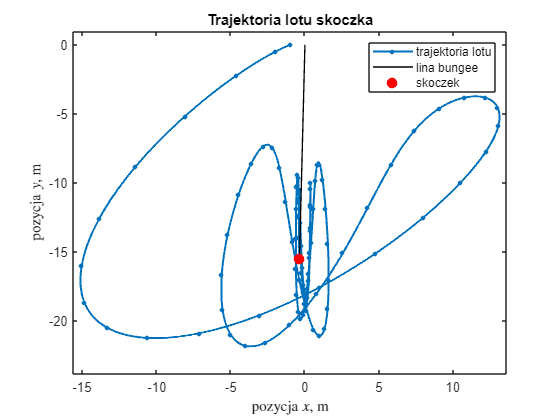

close all
t_1 = 30; % czas, (s)
narysuj_trajektorie_skoku(x,y,t_1,t_max)

## 8. Wykresy dodatkowe

Poniżej umieszczono kilka dodatkowych wykresów przedstawiających przebieg niektórych wielkości fizycznych w trakcie trwania skoku. Spróbuj zrozumieć przebieg przedstawionych wielkości fizycznych w czasie. Czy wykresy mają sens?

Zacznijmy od wykresów współrzędnych $x$ oraz $y$ skoczka w czasie, oraz jego prędkości i przyspieszenia w tych kierunkach.

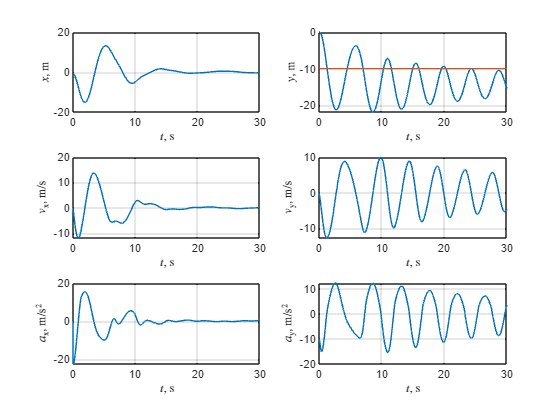

narysuj_parametry_ruchu(t,x,y,V,A,L)

Na kolejnych wykresach przedstawione będą przebiegi składowych $x$ oraz $y$ sił sprężystości liny, oporów ruchu oraz siły wypadkowej działającej na skoczka.

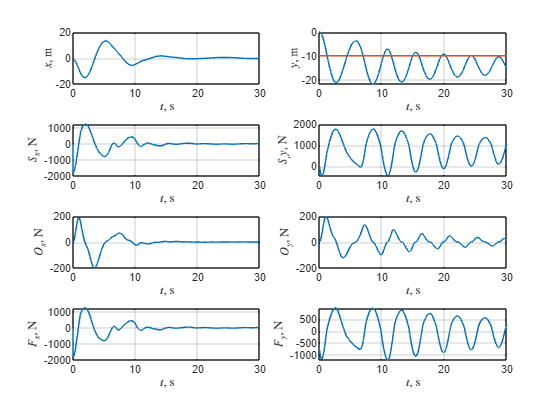

narysuj_sily(t,x,y,S,O,F,L)

Na koniec narysujemy wykresy przedstawiające przebieg w czasie współrzędnej $y$ skoczka, oraz wartości różnych składowych energii mechanicznej, tj. jego energii potencjalnej (grawitacji) oraz energii potencjalnej sprężystości liny. Dodatkowo, narysujemy również przebieg w czasie wartości całkowitej energii mechanicznej układu skoczek-lina. 

Spróbuj odpowiedzieć na pytanie czy poniższy wykres jest prawidłowy? Jak pogodzić przebieg wykresu z zasadą zachowania energii mechanicznej?

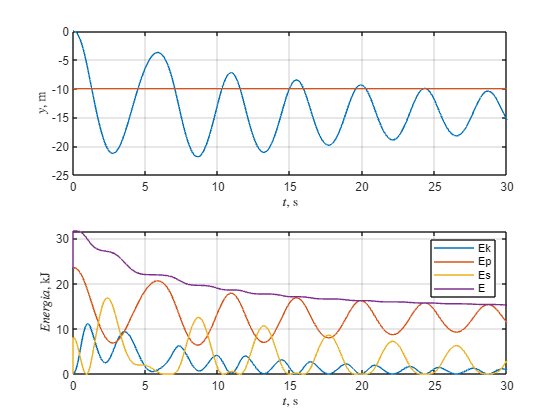

narysuj_energie(t,x,y,Ek,Ep,Es,E,L)

## DODATEK. Dopuszczalne wartości parametrów

Poniżej znajdują się parametry, które można zmieniać w danych skryptu, aby sprawdzić jak zmienią się wyniki symulacji.


$$H \in \ [20;50] \textrm{ m}$$



$$m \in \ [50; 150] \textrm{ kg}$$



$$L \in \ [6; 20] \textrm{ m}$$



$$x_s \in \ [0; -L] \textrm{ m}$$


Parametry liny bungee:

- sztywna - $k_1 = 250 \textrm{ N/m}$, $k_2 = 150 \textrm{ N/m}$,

- średnia - $k_1 = 200 \textrm{ N/m}$, $k_2 = 110 \textrm{ N/m}$,

- podatna - $k_1 = 160 \textrm{ N/m}$, $k_2 = 80 \textrm{ N/m}$,

- $e_b \in \ [4, 6] \textrm{ m}$.

Parametry oporów ruchu:

- 
$$\rho \in \ [1.1;1.3] \textrm{ kg/m}^3$$


- $C = 0.7$ dla skoku stopami do dołu oraz $C = 1.0$ dla skoku na płasko

- $A \in \ [0.65; 1.05] \textrm{ m}^2$, gdzie średnia powierzchnia kobiety to $0.8$, a mężczyzny $0.95$. 

Maksymalna siła w linie bungee $S_{max} \approx 20 \textrm{ kN}$.

Wskaźnik wydłużenia do długości początkowej $e/L \in \ [2;4]$